## Genetic Algorithm Optimization for the Generator

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


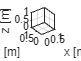

Unrecognized field name "coil_length".

Error in machine_parameters (line 106)
HTS.R_outer = HTS.R_mean + 0.5 * HTS.coil_length + HTS.coil_width; %[m], HTS Outer radius, similar calculation to stator

Error in optimization_cost (

% Set nondefault solver options
options = optimoptions("gamultiobj","PopulationSize",200,"MaxGenerations",...
    150,"UseParallel",true,"ConstraintTolerance",0.1,"FunctionTolerance",0.1,...
    "PlotFcn",["gaplotdistance","gaplotselection","gaplotscorediversity",...
    "gaplotscores","gaplotstopping","gaplotmaxconstr","gaplotrankhist",...
    "gaplotpareto","gaplotspread","gaplotparetodistance"]);

% Solve
[solution,objectiveValue] = gamultiobj(@optimization_cost,number_of_inputs,...
    [],[],[],[],lower_bounds,upper_bounds,[],IntCon,options);


% Clear variables
clearvars options